# Escuela Politécnica Nacional

# Chunk-based Malware Classifiers for Communication Networks

# (ANFIS)

# Proyecto de Fin de Módulo Redes Neuronales

**Autor:** David Cevallos

**Fecha:** 2023-08-15

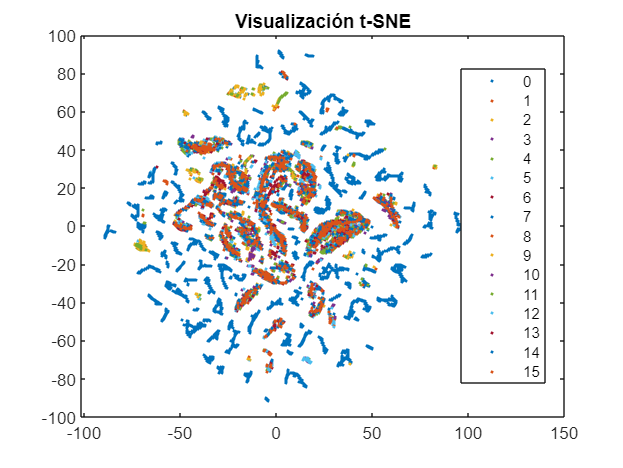

% Identificación y clasificación de Malware 
tic;
clc;
clear;
close all;
warning("off","all");
rng(0);

% Limpieza de datos
T = readtable("Obfuscated-MalMem2022.csv", "ReadVariableNames",true);

Categories = string(T.Category);
Categories(Categories.startsWith("Benign"))="0";
Categories(Categories.startsWith("Spyware-180solutions"))="1";
Categories(Categories.startsWith("Spyware-CWS"))="2";
Categories(Categories.startsWith("Spyware-Gator"))="3";
Categories(Categories.startsWith("Spyware-Transponder"))="4";
Categories(Categories.startsWith("Spyware-TIBS"))="5";
Categories(Categories.startsWith("Ransomware-Conti"))="6";
Categories(Categories.startsWith("Ransomware-Maze"))="7";
Categories(Categories.startsWith("Ransomware-Pysa"))="8";
Categories(Categories.startsWith("Ransomware-Ako"))="9";
Categories(Categories.startsWith("Ransomware-Shade"))="10";
Categories(Categories.startsWith("Trojan-Zeus"))="11";
Categories(Categories.startsWith("Trojan-Emotet"))="12";
Categories(Categories.startsWith("Trojan-Refroso"))="13";
Categories(Categories.startsWith("Trojan-Scar"))="14";
Categories(Categories.startsWith("Trojan-Reconyc"))="15";

X = table2array(T(:,2:end-1));
Y = double(Categories);

% Clases
orden = unique(Y);
min_clase = min(orden);
max_clase = max(orden);

% Hyperparameters tuning
% Mejor métrica: 1 Precision, 2 Recall, 3 F1-score, 4 Accuracy
% Por cada algoritmo se toma el modelo que proporcione la mejor
% métrica seleccionada
mejor_metrica = 3;

% Reducción de dimensionalidad
Y_tsne = tsne(X, "NumDimensions", 2, "Perplexity", 100);
Xred = [Y_tsne(:,1), Y_tsne(:,2)];

figure;
gscatter(Y_tsne(:,1), Y_tsne(:,2), Y);
title("Visualización t-SNE");


% Partición Holdout
rng(0);
cpart = cvpartition(Y,"Holdout", 0.2, "Stratify", true);

Xtrain = Xred(training(cpart),:);
Ytrain = Y(training(cpart),:);

Xtest = Xred(test(cpart),:);
Ytest = Y(test(cpart),:);

% Método 10-folding (Cross-validation)
CVO = cvpartition(Ytrain,"k",10,"Stratify",true);
num_pruebas = CVO.NumTestSets;

initials = [3];
n_epocas = [100];
methods = [0 1];
contador = 1;
rng(0);

for i = 1:length(initials)
    initial=initials(i,:);
    for j = 1: length(n_epocas)
        epocas=n_epocas(j);
        for k = 1: length(methods)
            method=methods(k);
            optTest = anfisOptions;
            optTest.InitialFIS = initial;
            optTest.EpochNumber = epocas;
            optTest.OptimizationMethod = method;
            optTest.DisplayANFISInformation = 0;
            optTest.DisplayErrorValues = 0;
            optTest.DisplayStepSize = 0;
            optTest.DisplayFinalResults = 0;

            for l = 1:num_pruebas
                trIdx = CVO.training(l);
                teIdx = CVO.test(l);
                anfis_model = anfis([Xred(trIdx,:) Y(trIdx,:)], optTest);
                Ypred_anfis = round(evalfis(anfis_model, Xred(teIdx,:)));
                Ypred_anfis(Ypred_anfis < min_clase) = min_clase;
                Ypred_anfis(Ypred_anfis > max_clase) = max_clase;
                Met_anfis(:,i) = Metricas(Y(teIdx,:), Ypred_anfis);
            end

            Metricas_anfis = mean(Met_anfis,2);
            Total_Metricas_anfis(:,contador) = Metricas_anfis;
            Parametros_anfis(:,contador)=[initial;epocas;method];
            contador = contador+1;
        end
    end
end

[~,col] = max(Total_Metricas_anfis(mejor_metrica,:));
fprintf("Mejor parametro Initials:");

Mejor parametro Initials:

disp(Parametros_anfis(1,col))

     3



fprintf("Mejor parametro Épocas:");

Mejor parametro Épocas:

disp(Parametros_anfis(2,col))

   100



fprintf("Mejor parametro Método:");

Mejor parametro Método:

disp(Parametros_anfis(3,col))

     0



fprintf("Métricas");

Métricas


fprintf("------------------------------------");

------------------------------------

fprintf("Resultados métricas cross-validation");

Resultados métricas cross-validation

fprintf("------------------------------------");

------------------------------------

Total_Metricas_anfis(:,col)

ans =     0.2031
    0.0941
    0.2406
    0.3115
    0.6885
    0.9246
    0.0754



% Evaluación del modelo (Test)
optTest = anfisOptions;
            optTest.InitialFIS = Parametros_anfis(1,col);
            optTest.EpochNumber = Parametros_anfis(2,col);
            optTest.OptimizationMethod = Parametros_anfis(3,col);
            optTest.DisplayANFISInformation = 0;
            optTest.DisplayErrorValues = 0;
            optTest.DisplayStepSize = 0;
            optTest.DisplayFinalResults = 0;
anfis_final_model = anfis([Xtrain Ytrain], optTest);
Ypred_test_anfis = round(evalfis(anfis_final_model, Xtest));
fprintf("------------------------------------");

------------------------------------

fprintf("Resultados métricas test");

Resultados métricas test

fprintf("------------------------------------");

------------------------------------

Metricas_test_anfis = Metricas(Ytest, Ypred_test_anfis)'

Metricas_test_anfis =     0.1110
    0.0766
    0.1266
    0.1918
    0.8082
    0.9494
    0.0506


toc

Elapsed time is 797.765607 seconds.
